%% Single-phase slightly compressible fluid (water)
%% Input concentration for formation and injected waters is in mole/kilogram
%% Cartesian grid model
clc, clear, close all

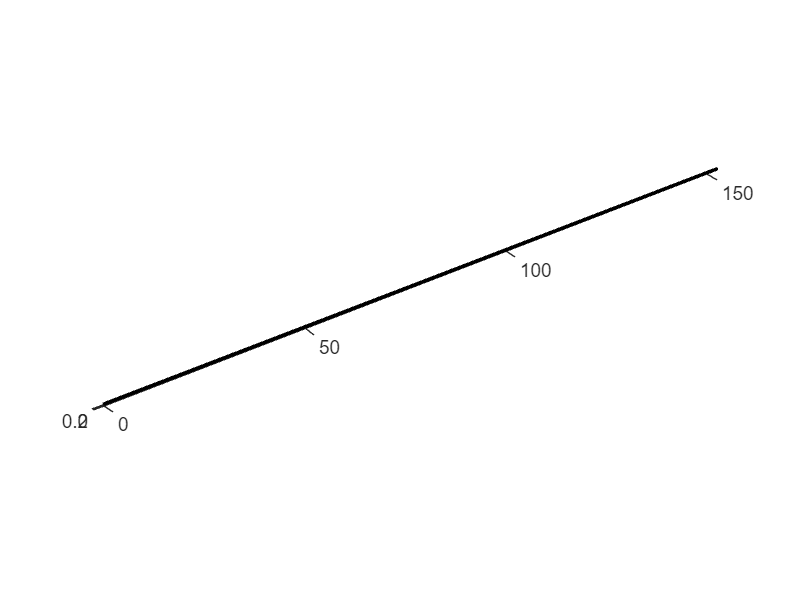

%% Define and descretize the domain
[nx,ny,nz] = deal(50, 1, 1);
[Lx,Ly,Lz] = deal(500*ft, 1*ft, 1*ft);
G = cartGrid([nx, ny, nz], [Lx, Ly, Lz]);
G = computeGeometry(G);

plotGrid(G); view(3); axis tight equal

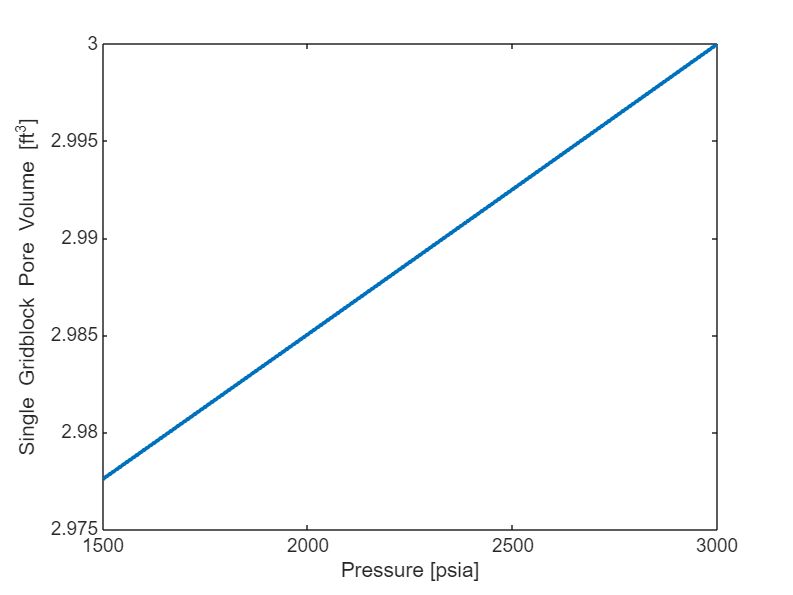

%% Define rock model
rock   = makeRock(G, 30*milli*darcy, 0.3);
cr     = 5e-6/psia;
Pref   = 3000*psia;
Dref   = 0.5*ft;
PVref  = poreVolume(G, rock);
PVfunc = @(P) PVref.*exp(cr*(P - Pref));

P = linspace(1500*psia,Pref,50);
plot(P/psia, PVref(1)*exp(cr*(P-Pref))/ft^3,'LineWidth',2);
xlabel('Pressure [psia]')
ylabel('Single Gridblock Pore Volume [ft^3]')

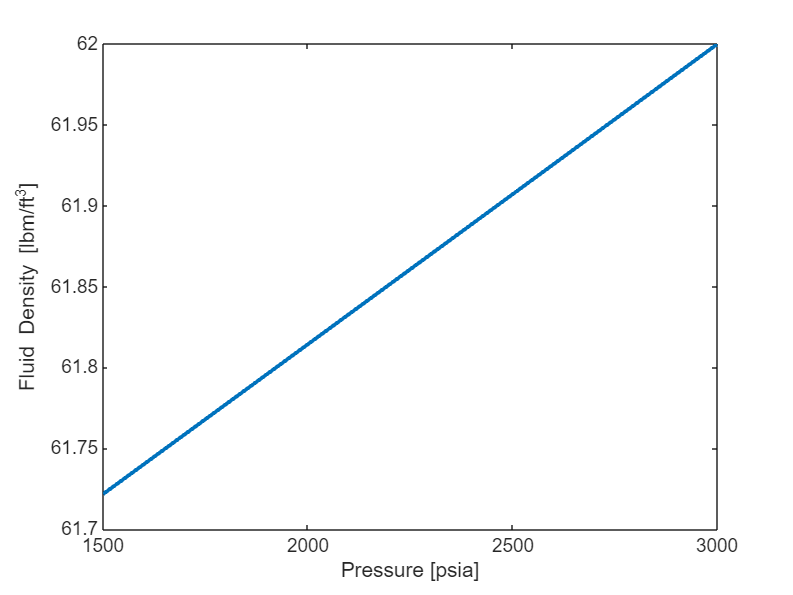

%% Define model for an slightly compressible fluid
mu     = 1*centi*poise;
cFluid = 3e-6/psia;
rhoRef = 62*pound/ft^3;    % reservoir fluid density at the reference conditions
rhoFunc = @(P) rhoRef*exp(cFluid*(P - Pref));

plot(P/psia,rhoFunc(P)/(pound/ft^3),'LineWidth',2);
xlabel('Pressure [psia]')
ylabel('Fluid Density [lbm/ft^3]')

%% Specify boundary conditions
nc = G.cells.num;
W = addWell([], G, rock,  1, 'Name', 'Injection Well' , 'Radius', 0.5*ft);
W = addWell(W , G, rock, nc, 'Name', 'Production Well', 'Radius', 0.5*ft);
injCell  = W(1).cells;
prodCell = W(2).cells;
PIprod = W(2).WI;    % well productivity indices
dzProd = W(2).dZ;    % perforated cell depth relative to bottom-hole
% Internal boundary conditions
qInj    = 0.1*stb/day;
BHPprod = Pref;
influxConc = 1*mol/kilogram;   %  mol of solvent in 1 kilogram of solution

gravity reset on, g = norm(gravity);
Pperf  = BHPprod + rhoFunc(BHPprod)*g.*dzProd; % wellbore pressures at perforated points

%% Set initial pressure and concentration
PG = rhoFunc(Pref)*g;
Pinit = Pref + PG.*(G.cells.centroids(:,3) - Dref);

Cinit = 0.5*mol/kilogram*ones(nc,1);

%% Compute transmissibilities
N  = double(G.faces.neighbors);             % Map: face -> cell
intInx = all(N ~= 0, 2);                    % Interior faces
N  = N(intInx, :);                          % Interior neighbors
hT = computeTrans(G, rock);                 % Half-transmissibilities
cf = G.cells.faces(:,1);                    % Map: cell -> face
nf = G.faces.num;                           % Total number of faces
T  = 1 ./ accumarray(cf, 1 ./ hT, [nf, 1]); % Harmonic average
T  = T(intInx);                             % Restricted to interior

%% Define discrete operators to desretize the mathematical equations
n = size(N,1);
C = sparse( [(1:n)'; (1:n)'], N, ones(n,1)*[-1 1], n, G.cells.num);
grad    = @(x)C*x;
div     = @(x)-C'*x;
avg     = @(x) 0.5 * (x(N(:,1)) + x(N(:,2)));
upwind  = @(x,flag) x(N(:,1)).*double(flag)+x(N(:,2)).*double(~flag);

%% Initialize for solution loop
[P_AD, C_AD] = initVariablesADI(Pinit, Cinit);
[pIx, cIx] = deal(1:nc, (nc+1):(2*nc));

numSteps = 50;                  % number of time-steps
totTime  = 150*day;             % total simulation time
dt       = totTime / numSteps;  % constant time step
tol      = 1e-5;                % Newton tolerance
maxIter  = 10;                  % max number of Newton-Raphson iterations

sol = repmat(struct('time',[],'pressure',[], 'C', []),[numSteps+1,1]);
sol(1)  = struct('time', 0, 'pressure', value(P_AD)/psia, 'C', value(C_AD));

%% Main loop
t = 0; step = 0;
hwb = waitbar(t,'Simulation ...');
while t < totTime
   t = t + dt;
   step = step + 1;
   fprintf('\nTime step %d: Time %.2f -> %.2f days\n', ...
      step, convertTo(t - dt, day), convertTo(t, day));

   P0  = value(P_AD);
   C0  = value(C_AD);

   % Newton loop
   resNorm = 1e+99;
   iterCounter = 0;
   while (resNorm > tol) && (iterCounter <= maxIter)
    %% Define pressure equation
      [rho_AD, rho0] = deal(rhoFunc(P_AD), rhoFunc(P0));
      [PV_AD , PV0]  = deal(PVfunc(P_AD), PVfunc(P0));
      gradz  = grad(G.cells.centroids(:,3));
      v = -(T/mu).*(grad(P_AD) - avg(rho_AD)*g.*gradz);
      pressEq = (1/dt)*(PV_AD.*rho_AD - PV0.*rho0) + div(avg(rho_AD).*v);

      % Adding boundary conditions
      qProd  = -PIprod.*(1/mu).*(P_AD(prodCell) - Pperf);
      % The BC of the production well can be set in 2 different ways, either using the BHP directly or using the equivalent production flowrate.
      pressEq(prodCell) = pressEq(prodCell) - qProd*rho_AD(prodCell); % Method 1
      %pressEq(prodCell) = P_AD(prodCell) - BHPprod;      % Method 2

      pressEq(injCell)  = pressEq(injCell) - qInj*rhoRef;
      %% Define the mass transport equation of the desired species
      % water upstream-index
      upcw = v > 0;
      accumTerm  = (1/dt).*(PV_AD.*rho_AD.*C_AD - PV0.*rho0.*C0);
      % Flux term without dispersion
%       fluxTerm   = div(upwind(C_AD.*rho_AD, upcw).*v);
      % Flux term with dispersion
      D = 10^(-9)*meter^2/second*ones;
      fluxTerm   = div(upwind(C_AD.*rho_AD, upcw).*v - avg(rock.poro.*rho_AD).*D.*grad(C_AD));

      transEq = accumTerm + fluxTerm;
      
      % Add boundary conditions
%       transEq(injCell)  = C_AD(injCell) - influxConc;   % Method 1
      transEq(injCell)  = transEq(injCell) - qInj*rhoRef*influxConc;   % Method 2
      transEq(prodCell) = transEq(prodCell) - qProd*rho_AD(prodCell)*C_AD(prodCell);

      %% Collect and concatenate all equations (i.e., assemble and linearize system)
      eqs = {pressEq, transEq};
      eq  = cat(eqs{:});
      J   = eq.jac{1};  % Jacobian
      res = eq.val;     % residual
      increment = -(J \ res); % Newton update

      %% Update variables
      P_AD.val   = P_AD.val + increment(pIx);
      C_AD.val   = C_AD.val + increment(cIx);

      resNorm = norm(res);
      iterCounter   = iterCounter + 1;
      fprintf('  Iteration %3d:  Res = %.4e\n', iterCounter, resNorm);
   end

   if iterCounter > maxIter
      error('Newton solver did not converge')
   else % Store solution
      sol(step+1)  = struct('time', t, 'pressure', value(P_AD)/psia, 'C', value(C_AD));
      waitbar(t/totTime,hwb);
   end
end


Time step 1: Time 0.00 -> 3.00 days


  Iteration   1:  Res = 2.7378e-04
  Iteration   2:  Res = 7.2353e-05
  Iteration   3:  Res = 1.1593e-07



Time step 2: Time 3.00 -> 6.00 days


  Iteration   1:  Res = 6.6287e-05
  Iteration   2:  Res = 3.9126e-07



Time step 3: Time 6.00 -> 9.00 days


  Iteration   1:  Res = 5.0006e-05
  Iteration   2:  Res = 8.0947e-08



Time step 4: Time 9.00 -> 12.00 days


  Iteration   1:  Res = 4.2431e-05
  Iteration   2:  Res = 2.2330e-08



Time step 5: Time 12.00 -> 15.00 days


  Iteration   1:  Res = 3.8212e-05
  Iteration   2:  Res = 6.4343e-09



Time step 6: Time 15.00 -> 18.00 days


  Iteration   1:  Res = 3.5500e-05
  Iteration   2:  Res = 1.8777e-09



Time step 7: Time 18.00 -> 21.00 days


  Iteration   1:  Res = 3.3559e-05
  Iteration   2:  Res = 5.5132e-10



Time step 8: Time 21.00 -> 24.00 days


  Iteration   1:  Res = 3.2064e-05
  Iteration   2:  Res = 1.6248e-10



Time step 9: Time 24.00 -> 27.00 days


  Iteration   1:  Res = 3.0857e-05
  Iteration   2:  Res = 4.8008e-11



Time step 10: Time 27.00 -> 30.00 days


  Iteration   1:  Res = 2.9848e-05
  Iteration   2:  Res = 1.4209e-11



Time step 11: Time 30.00 -> 33.00 days


  Iteration   1:  Res = 2.8986e-05
  Iteration   2:  Res = 4.2107e-12



Time step 12: Time 33.00 -> 36.00 days


  Iteration   1:  Res = 2.8236e-05
  Iteration   2:  Res = 1.2488e-12



Time step 13: Time 36.00 -> 39.00 days


  Iteration   1:  Res = 2.7573e-05
  Iteration   2:  Res = 3.7061e-13



Time step 14: Time 39.00 -> 42.00 days


  Iteration   1:  Res = 2.6982e-05
  Iteration   2:  Res = 1.1003e-13



Time step 15: Time 42.00 -> 45.00 days


  Iteration   1:  Res = 2.6448e-05
  Iteration   2:  Res = 3.2675e-14



Time step 16: Time 45.00 -> 48.00 days


  Iteration   1:  Res = 2.5964e-05
  Iteration   2:  Res = 9.7055e-15



Time step 17: Time 48.00 -> 51.00 days


  Iteration   1:  Res = 2.5520e-05
  Iteration   2:  Res = 2.8830e-15



Time step 18: Time 51.00 -> 54.00 days


  Iteration   1:  Res = 2.5112e-05
  Iteration   2:  Res = 8.5861e-16



Time step 19: Time 54.00 -> 57.00 days


  Iteration   1:  Res = 2.4735e-05
  Iteration   2:  Res = 2.7055e-16



Time step 20: Time 57.00 -> 60.00 days


  Iteration   1:  Res = 2.4384e-05
  Iteration   2:  Res = 8.8449e-17



Time step 21: Time 60.00 -> 63.00 days


  Iteration   1:  Res = 2.4056e-05
  Iteration   2:  Res = 3.0463e-17



Time step 22: Time 63.00 -> 66.00 days


  Iteration   1:  Res = 2.3750e-05
  Iteration   2:  Res = 1.0218e-16



Time step 23: Time 66.00 -> 69.00 days


  Iteration   1:  Res = 2.3461e-05
  Iteration   2:  Res = 8.1856e-17



Time step 24: Time 69.00 -> 72.00 days


  Iteration   1:  Res = 2.3190e-05
  Iteration   2:  Res = 2.8513e-17



Time step 25: Time 72.00 -> 75.00 days


  Iteration   1:  Res = 2.2933e-05
  Iteration   2:  Res = 2.4417e-17



Time step 26: Time 75.00 -> 78.00 days


  Iteration   1:  Res = 2.2690e-05
  Iteration   2:  Res = 3.5592e-17



Time step 27: Time 78.00 -> 81.00 days


  Iteration   1:  Res = 2.2459e-05
  Iteration   2:  Res = 3.7886e-17



Time step 28: Time 81.00 -> 84.00 days


  Iteration   1:  Res = 2.2239e-05
  Iteration   2:  Res = 3.8147e-17



Time step 29: Time 84.00 -> 87.00 days


  Iteration   1:  Res = 2.2029e-05
  Iteration   2:  Res = 3.7599e-17



Time step 30: Time 87.00 -> 90.00 days


  Iteration   1:  Res = 2.1829e-05
  Iteration   2:  Res = 3.7625e-17



Time step 31: Time 90.00 -> 93.00 days


  Iteration   1:  Res = 2.1638e-05
  Iteration   2:  Res = 3.6938e-17



Time step 32: Time 93.00 -> 96.00 days


  Iteration   1:  Res = 2.1455e-05
  Iteration   2:  Res = 3.6958e-17



Time step 33: Time 96.00 -> 99.00 days


  Iteration   1:  Res = 2.1279e-05
  Iteration   2:  Res = 3.7002e-17



Time step 34: Time 99.00 -> 102.00 days


  Iteration   1:  Res = 2.1110e-05
  Iteration   2:  Res = 3.7035e-17



Time step 35: Time 102.00 -> 105.00 days


  Iteration   1:  Res = 2.0947e-05
  Iteration   2:  Res = 3.7031e-17



Time step 36: Time 105.00 -> 108.00 days


  Iteration   1:  Res = 2.0791e-05
  Iteration   2:  Res = 3.7096e-17



Time step 37: Time 108.00 -> 111.00 days


  Iteration   1:  Res = 2.0640e-05
  Iteration   2:  Res = 3.7124e-17



Time step 38: Time 111.00 -> 114.00 days


  Iteration   1:  Res = 2.0494e-05
  Iteration   2:  Res = 3.7140e-17



Time step 39: Time 114.00 -> 117.00 days


  Iteration   1:  Res = 2.0353e-05
  Iteration   2:  Res = 3.7178e-17



Time step 40: Time 117.00 -> 120.00 days


  Iteration   1:  Res = 2.0217e-05
  Iteration   2:  Res = 3.7211e-17



Time step 41: Time 120.00 -> 123.00 days


  Iteration   1:  Res = 2.0085e-05
  Iteration   2:  Res = 3.7232e-17



Time step 42: Time 123.00 -> 126.00 days


  Iteration   1:  Res = 1.9958e-05
  Iteration   2:  Res = 3.7261e-17



Time step 43: Time 126.00 -> 129.00 days


  Iteration   1:  Res = 1.9834e-05
  Iteration   2:  Res = 3.7247e-17



Time step 44: Time 129.00 -> 132.00 days


  Iteration   1:  Res = 1.9714e-05
  Iteration   2:  Res = 3.7297e-17



Time step 45: Time 132.00 -> 135.00 days


  Iteration   1:  Res = 1.9597e-05
  Iteration   2:  Res = 3.7315e-17



Time step 46: Time 135.00 -> 138.00 days


  Iteration   1:  Res = 1.9484e-05
  Iteration   2:  Res = 3.7361e-17



Time step 47: Time 138.00 -> 141.00 days


  Iteration   1:  Res = 1.9374e-05
  Iteration   2:  Res = 3.7355e-17



Time step 48: Time 141.00 -> 144.00 days


  Iteration   1:  Res = 1.9267e-05
  Iteration   2:  Res = 3.7420e-17



Time step 49: Time 144.00 -> 147.00 days


  Iteration   1:  Res = 1.9163e-05
  Iteration   2:  Res = 3.7421e-17



Time step 50: Time 147.00 -> 150.00 days


  Iteration   1:  Res = 1.9061e-05
  Iteration   2:  Res = 3.7455e-17


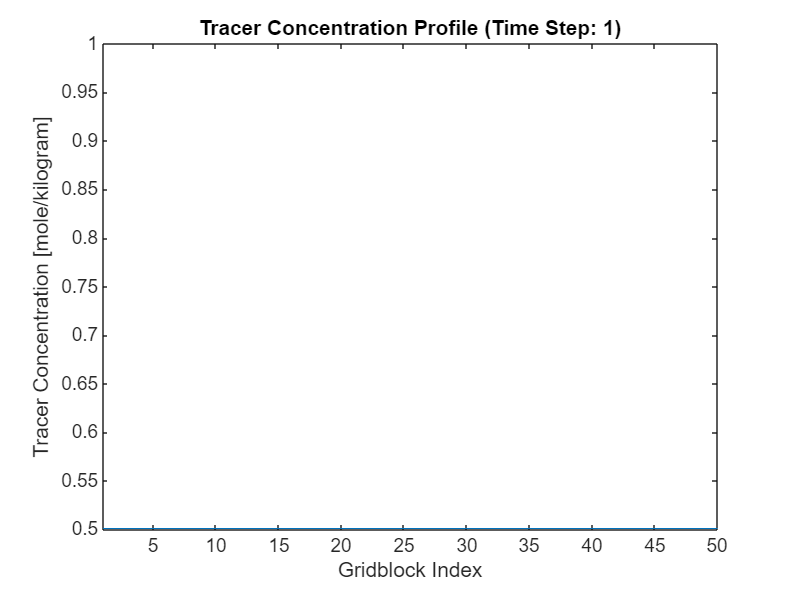

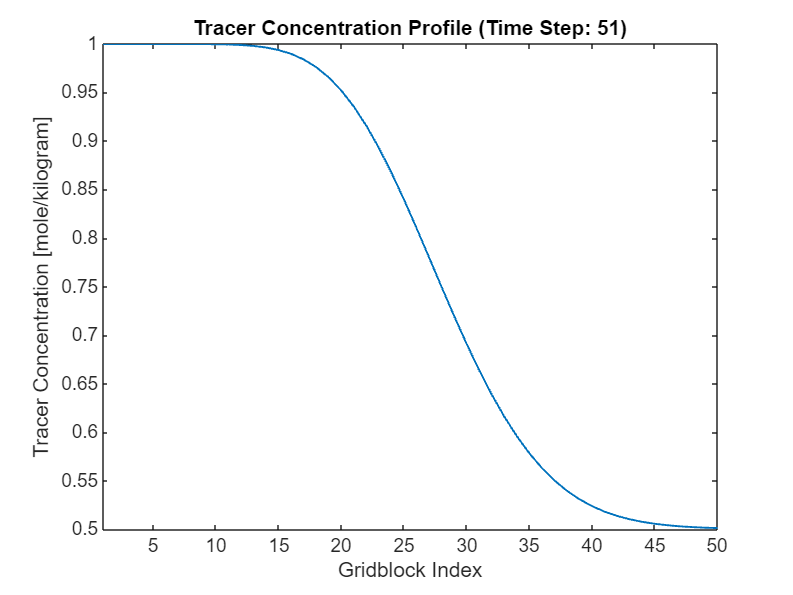

close(hwb);
%% For a 1-dimensional domain
clf
for i = 1:numel(sol)
    plot(1:nc, sol(i).C, 'LineWidth', 1)
    title(['Tracer Concentration Profile (', 'Time Step: ', num2str(i),')'])
    xlim([1,nc])
    ylim([Cinit(1), influxConc])
    xlabel('Gridblock Index')
    ylabel('Tracer Concentration [mole/kilogram]')
    pause(0.25)
end

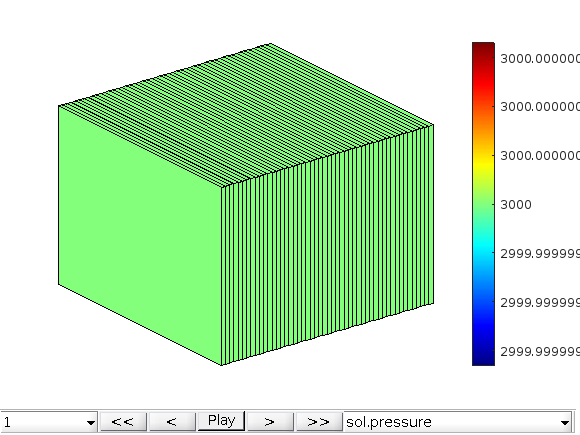

%% MRST-GUI
mrstModule add mrst-gui
plotToolbar(G, sol)
view(3)
colorbar
colormap(jet)
shading faceted
axis tight
axis off